## Задание 2. Исследование LQE/фильтра Калмана.

Начальные условия на задание:

A = [-35 11 6 11; 
     -56 17 10 18;
     -22 7 5 6;
     -42 12 10 13];
mat2tex(A,2);

\begin{bmatrix}
    -35 & 11 & 6 & 11 \\
    -56 & 17 & 10 & 18 \\
    -22 & 7 & 5 & 6 \\
    -42 & 12 & 10 & 13 \\
\end{bmatrix}


C = [-1, 0, 0, 1]

C =     -1     0     0     1


mat2tex(C,2);

\begin{bmatrix}
    -1 & 0 & 0 & 1 \\
\end{bmatrix}


% A = [20 5 -16 9;
%     6 1 -4 1;
%     32 9 -25 14;
%     8 4 -6 4];
% 
% C = [-1 0 1 -1];


** ( Для четных вариантов )Случайными сигналами f(t) и ξ(t) (гауссовский белый шум), исследуя таким образом фильтр Калмана. **

Какая система будет то?

V = obsv(A, C)

V =     -1     0     0     1
    -7     1     4     2
    17    -8     8    -9
    55    -1   -28   -26


mat2tex(V,2)

\begin{bmatrix}
    -1 & 0 & 0 & 1 \\
    -7 & 1 & 4 & 2 \\
    17 & -8 & 8 & -9 \\
    55 & -1 & -28 & -26 \\
\end{bmatrix}


ans =     "\begin{bmatrix}
         -1 & 0 & 0 & 1 \\
         -7 & 1 & 4 & 2 \\
         17 & -8 & 8 & -9 \\
         55 & -1 & -28 & -26 \\
     \end{bmatrix}"


rank(V)

ans = 4

**Наблюдаема+обнаруживаема**

eig(A)

ans =   -0.0000 + 3.0000i
  -0.0000 - 3.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


**Система получается полностью обнаруживаема!**

nu = 1;

Зададим дисперсию для белого шума

white_noise_var = 7;
gaussian_mean = 0;
gaussian_var = 4;

A [random vector](https://en.wikipedia.org/wiki/Random_vector) (that is, a random variable with values in *R**n*) is said to be a white noise vector or white random vector if its components each have a [probability distribution](https://en.wikipedia.org/wiki/Probability_distribution) with zero mean and finite [variance](https://en.wikipedia.org/wiki/Variance),[[*clarification needed*](https://en.wikipedia.org/wiki/Wikipedia:Please_clarify)] and are [statistically independent](https://en.wikipedia.org/wiki/Statistically_independent).

**Настройка моделирования**

x0 = [1 1 1 1]';        % plant
x_hat0 = [0 0 0 0]';   % observer
simTimeStart = 0;
simTimeEnd = 15;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer_noise'; 
load_system(modelName);

Выбираем Q,R, \alpha ...

a = 15;
Q = diag([2, 2, 2, 2]);
R = 4; 
% Скорость (качество переходного процесса) VS затраты (управление)

## **Набор (Q, R)**

Q = diag([2, 2, 2, 2]);
R = 4; 

P = are(A', 1*C'*R^-1 *C, Q)

P =   165.5827  270.0039  127.8147  202.6848
  270.0039  444.0251  208.0930  329.9350
  127.8147  208.0930  104.0232  157.9678
  202.6848  329.9350  157.9678  254.1323


L = -P*C'*R^-1

L =    -9.2755
  -14.9828
   -7.5383
  -12.8619


mat2tex(L,2);

\begin{bmatrix}
    -9.28 \\
    -14.98 \\
    -7.54 \\
    -12.86 \\
\end{bmatrix}


eig(A + L*C)

ans =   -1.1531 + 3.1733i
  -1.1531 - 3.1733i
  -0.6401 + 1.0813i
  -0.6401 - 1.0813i


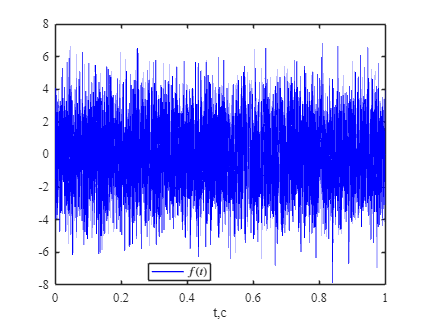

% LQR FUNCTION METHOD
% [L, P, ~] = lqr(A', C', Q, R)
% L = -L'
% e = eig(A+L*C)

%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;
f = squeeze(out.f.Data);
xi = out.xi.Data;

% Выбранные f(t) и \xi(t)
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% f(t)
plot(time, f, 'b', 'LineWidth',1);
xlabel('t,c'); ylabel(' ');
title(' ')
legend('$f(t)$','Interpreter','latex','Location','best')
xlim([0 1])
save_file("f(t)");

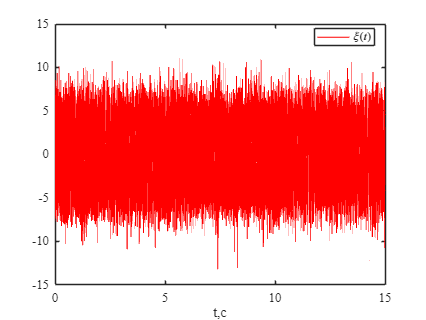


h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% xi(t)
plot(time, xi, 'r', 'LineWidth',1);
xlabel('t,c'); ylabel(' ');
title(' ')
legend('$\xi (t)$','Interpreter','latex','Location','best') 
save_file("xi(t)");

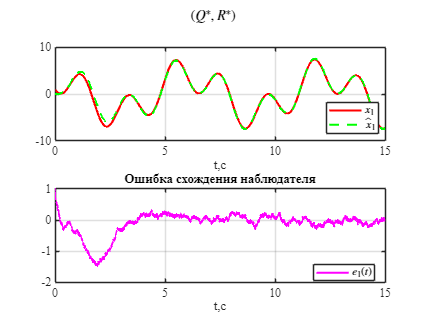

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, R^*)$','Interpreter','latex')
save_file("obsv1");

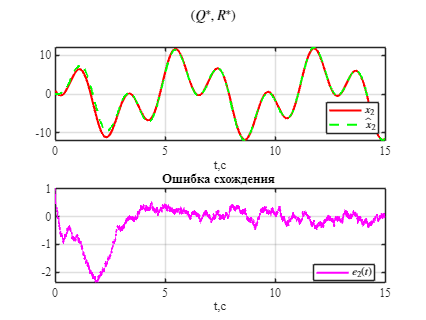

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, R^*)$','Interpreter','latex')
save_file("obsv2");

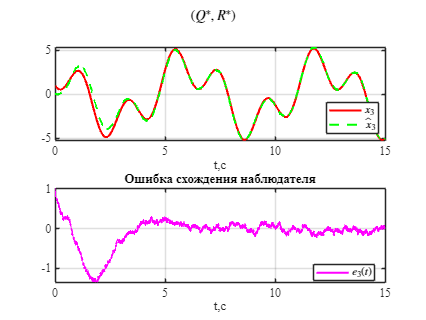

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, R^*)$','Interpreter','latex')
save_file("obsv3");

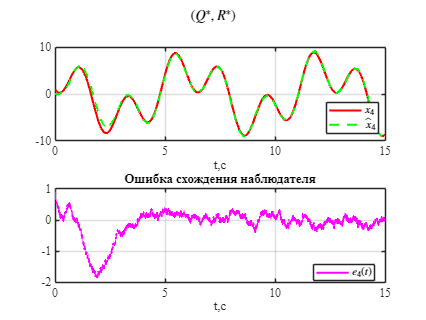

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, R^*)$','Interpreter','latex')
save_file("obsv4");

%%%%%%%%%%%%%%

## **Набор (aQ, R)**

Q = a * diag([2, 2, 2, 2]);
R = 4; 

P = are(A', 1*C'*R^-1 *C, Q)

P = 1.0e+03 *

    0.8443    1.4346    0.7145    0.9105
    1.4346    2.4748    1.1947    1.5431
    0.7145    1.1947    0.6481    0.7839
    0.9105    1.5431    0.7839    1.0119


L = -P*C'*R^-1

L =   -16.5331
  -27.1105
  -17.3546
  -25.3688


mat2tex(L,2);

\begin{bmatrix}
    -16.53 \\
    -27.11 \\
    -17.35 \\
    -25.37 \\
\end{bmatrix}


eig(A + L*C)

ans =   -3.5445 + 3.7839i
  -3.5445 - 3.7839i
  -0.8734 + 1.2280i
  -0.8734 - 1.2280i


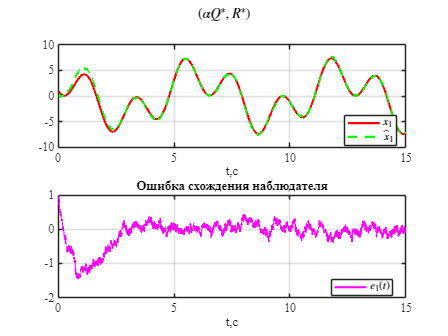


%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha Q^*, R^*)$','Interpreter','latex')
save_file("obsv5");

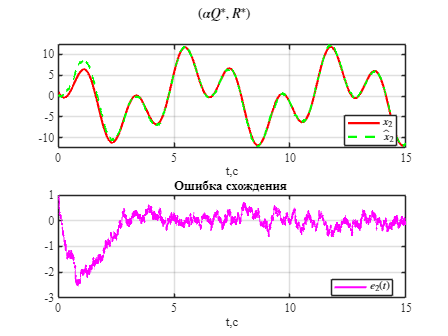

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha Q^*, R^*)$','Interpreter','latex')
save_file("obsv6");

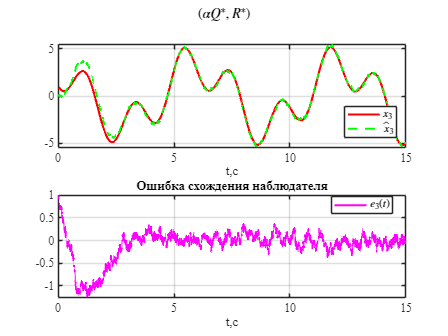

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha Q^*, R^*)$','Interpreter','latex')
save_file("obsv7");

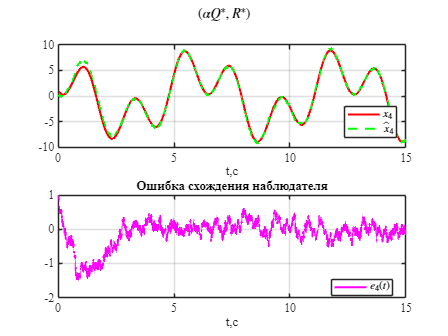

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(\alpha Q^*, R^*)$','Interpreter','latex')
save_file("obsv8");

## **Набор (Q, aR)**

Q = diag([2, 2, 2, 2]);
R = a * 4; 

P = are(A', 1*C'*R^-1 *C, Q)

P = 1.0e+03 *

    0.8577    1.3629    0.6089    1.0670
    1.3629    2.1769    0.9701    1.6969
    0.6089    0.9701    0.4453    0.7625
    1.0670    1.6969    0.7625    1.3431


L = -P*C'*R^-1

L =    -3.4886
   -5.5659
   -2.5591
   -4.6024


mat2tex(L,2);

\begin{bmatrix}
    -3.49 \\
    -5.57 \\
    -2.56 \\
    -4.6 \\
\end{bmatrix}


eig(A + L*C)

ans =   -0.3251 + 3.0183i
  -0.3251 - 3.0183i
  -0.2318 + 1.0080i
  -0.2318 - 1.0080i


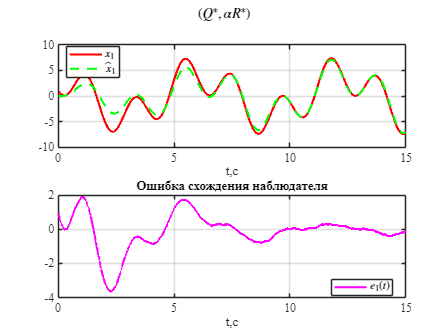


%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv9");

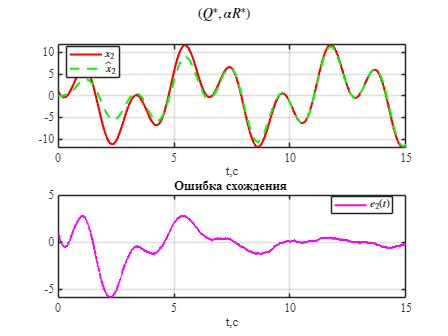

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv10");

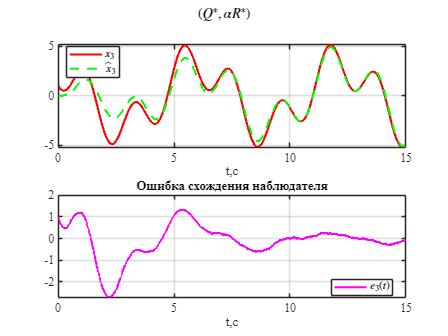

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv11");

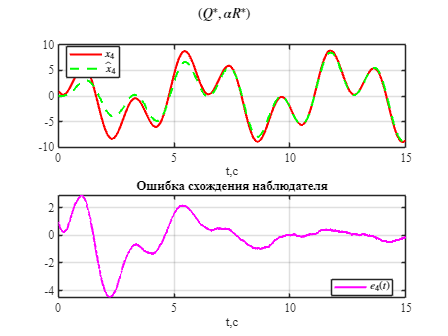

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$(Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv12");

## **4. Набор - (aQ, aR)**

Q = a * diag([2, 2, 2, 2])

Q =     30     0     0     0
     0    30     0     0
     0     0    30     0
     0     0     0    30


R = a * 4

R = 60


P = are(A', 1*C'*R^-1 *C, Q)

P = 1.0e+03 *

    2.4837    4.0501    1.9172    3.0403
    4.0501    6.6604    3.1214    4.9490
    1.9172    3.1214    1.5603    2.3695
    3.0403    4.9490    2.3695    3.8120


L = -P*C'*R^-1

L =    -9.2755
  -14.9828
   -7.5383
  -12.8619


mat2tex(L,2);

\begin{bmatrix}
    -9.28 \\
    -14.98 \\
    -7.54 \\
    -12.86 \\
\end{bmatrix}


eig(A + L*C)

ans =   -1.1531 + 3.1733i
  -1.1531 - 3.1733i
  -0.6401 + 1.0813i
  -0.6401 - 1.0813i


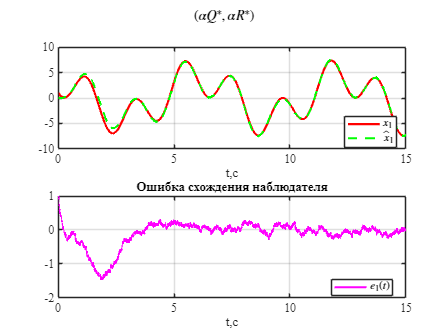


%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$( \alpha Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv13");

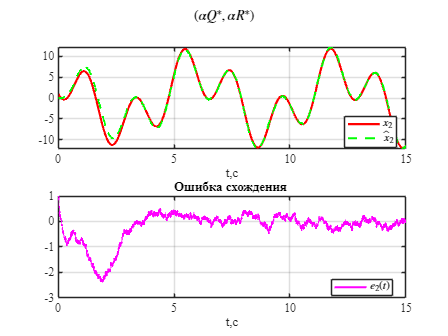

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$( \alpha Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv14");

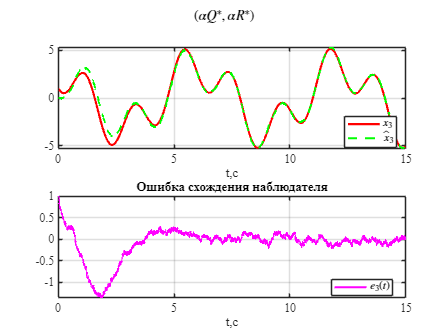

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$( \alpha Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv15");

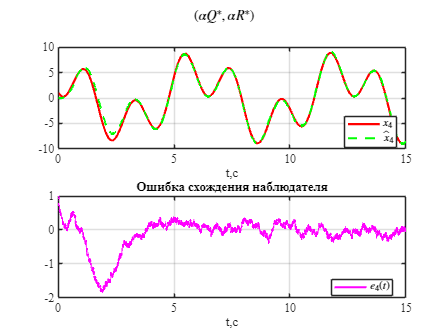

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$( \alpha Q^*, \alpha R^*)$','Interpreter','latex')
save_file("obsv16");

## Идеальный набор - знаем параметры шума


% Q = diag([gaussian_var, gaussian_var, gaussian_var, gaussian_var])^-1;
% R = white_noise_var^-1;
Q = diag([white_noise_var, white_noise_var, white_noise_var, white_noise_var]);
R = gaussian_var;

P = are(A', 1*C'*R^-1 *C, Q)

P =   304.0832  506.2804  248.0242  354.2358
  506.2804  853.0538  409.6711  587.8599
  248.0242  409.6711  215.9239  292.8914
  354.2358  587.8599  292.8914  426.6111


L = -P*C'*R^-1

L =   -12.5382
  -20.3949
  -11.2168
  -18.0938


mat2tex(L,2);

\begin{bmatrix}
    -12.54 \\
    -20.39 \\
    -11.22 \\
    -18.09 \\
\end{bmatrix}


eig(A + L*C)

ans =   -1.9782 + 3.3847i
  -1.9782 - 3.3847i
  -0.7996 + 1.1603i
  -0.7996 - 1.1603i


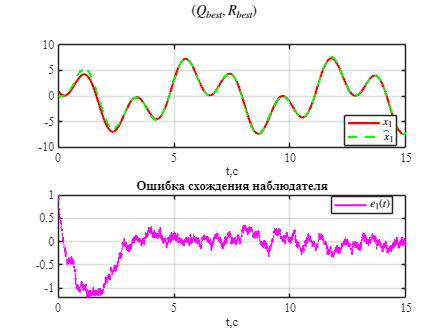


%%%___________%%%

out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

%%%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
sgtitle('$( Q_{best}, R_{best})$','Interpreter','latex')
save_file("obsv17");

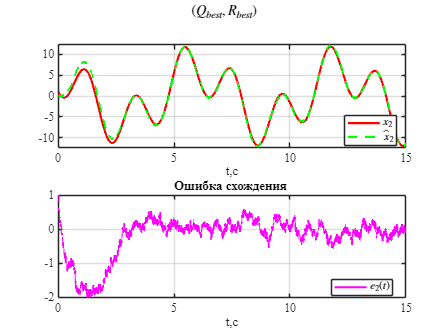

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
sgtitle('$( Q_{best}, R_{best})$','Interpreter','latex')
save_file("obsv18");

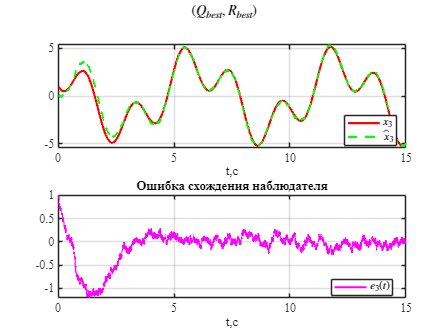

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
sgtitle('$( Q_{best}, R_{best})$','Interpreter','latex')
save_file("obsv19");

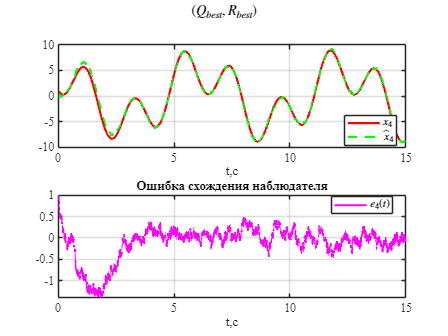

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
 title(' ')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
sgtitle('$( Q_{best}, R_{best})$','Interpreter','latex')
save_file("obsv20");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab10\latex10\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end